# Robotic toolbox 

# 1. Describe orientation and position, i.e. Pose

## 2D  case

### orthonormal Rotation Matrix

rotation matrix belong to the "special othogonal group $R\in SO
$

syms theta R(theta)
R = rot2(theta);

the corresponding  class is 

% SO2(theta)

### homogeneous transformation 

represent the pose or the motion of a rigid body, they belongs to the *special euclidian group ****SE.***

The composistion of homogenous transformations is given by the standard matrix product.

syms x y

T = [ R ; 0 0 ];
T = [T, [x y 0]']

$$T = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & \bar{x}\\ \sin\left(\theta \right) & \cos\left(\theta \right) & \bar{y}\\ 0 & 0 & 0 \end{array}\right)$$

#### create homogeneous transfomation $T$ in the toolbox:

- `transl2 = ` create a 2D relative pose of a pure translation

- `trot2 = `create a 2D relative pose of pure rotation

there are also specific classes that improve the readibility of the code

- `SO2 = rotation matrix in two dim`

- `SE2 = homogeneous transformation matrix `

%% translate by (1,2) and rotate by 30  degree: 
% composition of a pure translation + pure rotatation

% usinf function
T1 = transl2(1,2)* trot2(30,'deg')

T1 =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


% using SE class
T1 = SE2(1,2,30,'deg')

 

T1 = 
    0.8660   -0.5000         1
    0.5000    0.8660         2
         0         0         1


#### plot homogeneous transformation matrix

plotvol([0 5 0 5]), hold on 

trplot2(T1,'frame', '1','color','b') 
trplot2(rot2(0),'frame','origin','color','r')

since T1 is an isntance of the class 'SE2' we can also use the methods of this class

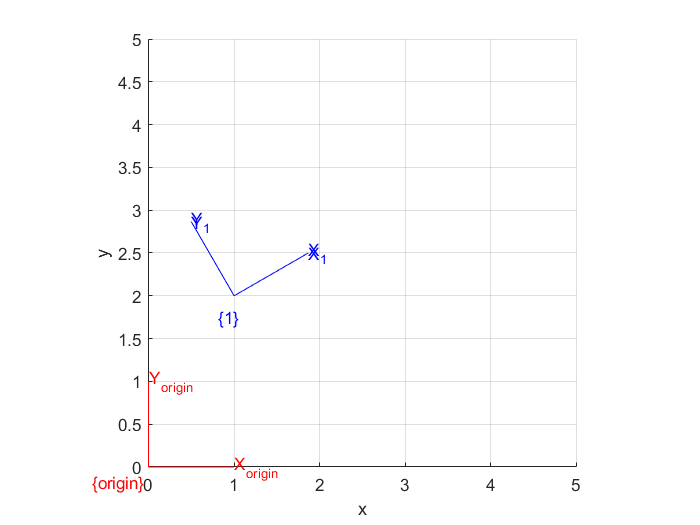

T1.animate

#### homogenous matrix composition is not commutative

define T2 as a pure traslation of [2,1]

T2 = SE2(2,1);

compute:

T12 = T1 T2, starting from {0} we first apply T1, arriving at {1}  and the translate by [1,2] w.r.t. this frame. 

T12 = T1*T2;
trplot2(T12,'frame','12','color','g')

T21 = T2 T1, starting from {0} we apply T2 arriving at {2}, i.e. we translate w.r.t. the {0}, then starting from this we apply T1 (translation of [1,2] and a rotation of 30 degree)

T21 = T2*T1;
trplot2(T2,'frame','2','color','c')
trplot2(T21,'frame','21','color','m')

#### example of non commutative of rotations

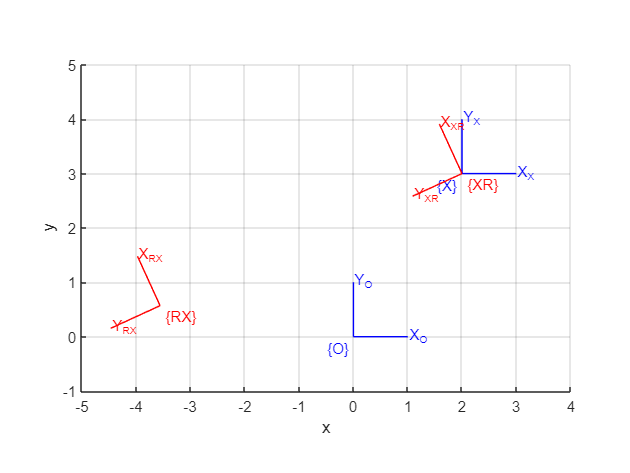

clf
plotvol([-5 4 -1 5])
origin = eye(3);
trplot2(origin,'frame','O');
% create target plot
X = SE2(2,3);
X.trplot2('frame','X')

% rotation matrix of 2 rad
R = SE2(0,0,2);
% plot the effect of the two possible order of composition
XR = X*R; 
XR.trplot2('color','r','frame','XR')
RX = R*X;
RX.trplot2('color','r','frame','RX')

### Rotation about an arbitrary point

In this section we explain how to rotate a frame around an arbitrary point $C$

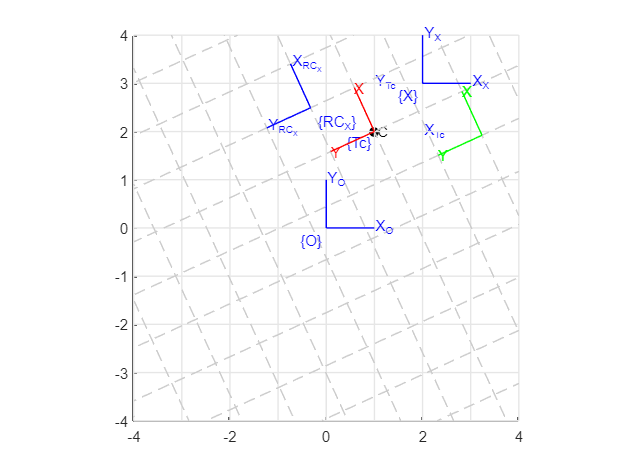

clf
%plotvol([-5 4 -1 5])
C = [1,2]';
plot_point(C,'label','C','solid','ko'), hold on, axis equal,axis([-5 4 -1 5]), 
Tc = SE2(C); Tc.trplot2('frame','Tc')
R = SE2(0,0,2);

rot_grid(-10:10, -10:10,R,C) % plot a grid rotated by R

% 1. translate to C and rotate 
TcR = Tc*R; TcR.trplot2('color','r')

% 2. apply the inverse translation: in this way frame O has rotated around C
TcRTc = Tc*R*Tc.inv; TcRTc.trplot2('color','g')

% We can now apply this transform to any vector expressed in O frame:
% for example we can apply to X
X.trplot2('frame','X')
trplot2(TcRTc*X,'frame','RC_X')
trplot2(origin,'frame','O')

A rapid way to rotate a frame around a point is to use the `Twist `method.

#### change of coordinate for vector representation 

starting from a point expressed in the base {0} frame we represent it in the {1} frame


$$p^o =T_1^0p^1  \\ p^1 = (T_1^0)^{-1}p^0$$


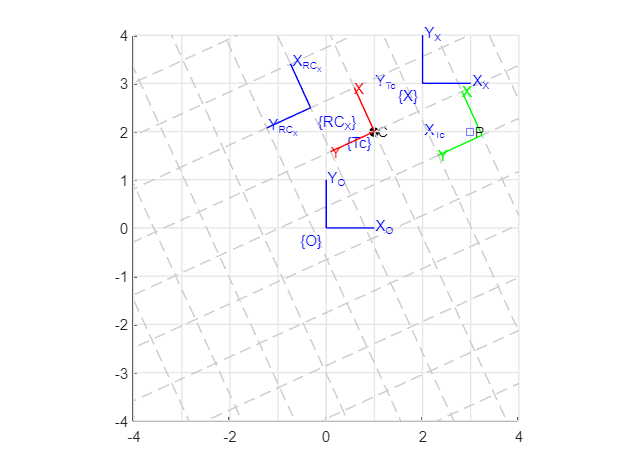

P = [3;2];
plot_point(P,'label','P')


P_1 = inv(T1.T)*[P;1] % coordinate of p in {1}, we have to transform T1 into an array

P_1 =     1.7321
   -1.0000
    1.0000


class(T1),class(T1.T)

ans = 'SE2'

ans = 'double'

#### conversion between euclidean and homogeneous coordinate

- `e2h `

- `h2e`

e2h(P)

ans =      3
     2
     1


## 3D case

by euler theorem every rotation can be decomposed in a combination of three elematary rotation about three axis such that wo consecutive rotaations aren't about the same axis.

### Elementary rotations


$$R_x(\theta) ,\ R_y(\theta), \ R_z(\theta)$$


Rx = rotx(pi/2) % angle is expressed in radians

Rx =      1     0     0
     0     0    -1
     0     1     0


Ry = roty(pi/4);
Rz = rotz(pi);

we can plot the pose corresponding to the given rotation matrix 

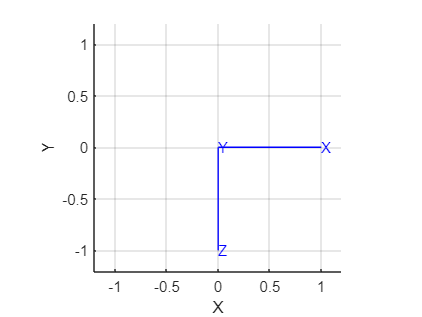

trplot(Rx)

and we can also animate the rotation that goes from the origanal (base  frame) to the transformed frame

figure('Visible','on')
tranimate(Rx)

### Three-angle representations

we need only to specify three angles and axes of rotations.

#### ZYZ sequence (euler sequence)


$$R = R_z(\phi)R_Y(\theta)R_z(\psi)$$


is the convention used in the toolbox, can be computed as

syms phi theta psi
R = rotz(phi)*roty(theta)*rotz(psi);

or more rapidly as

R = eul2r(phi,theta,psi)

$$R = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ -\cos\left(\psi \right)\,\sin\left(\theta \right) & \sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

to find the three angle corresponding to a rotation matrix we use

- `tr2euler(R)`

this operation is not unique and the toolbox always return the positive value of the angle $\theta$

### Roll-Pitch-Yaw ( Cardan sequence)

# Homogeneous transformation

T1 =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


T2 =      1     0     2
     0     1     1
     0     0     1


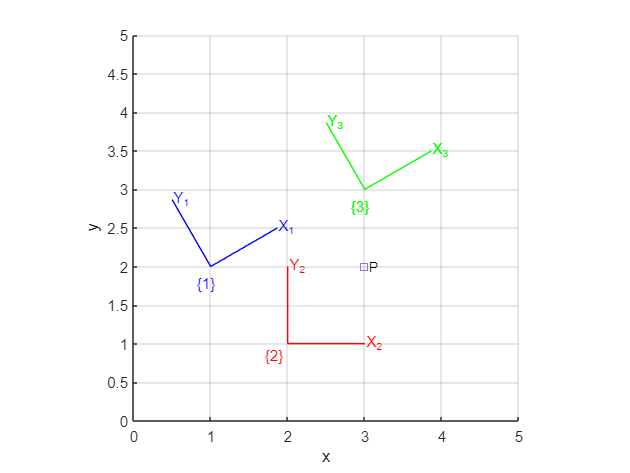

P_1 =     1.7321
   -1.0000
    1.0000


hold off

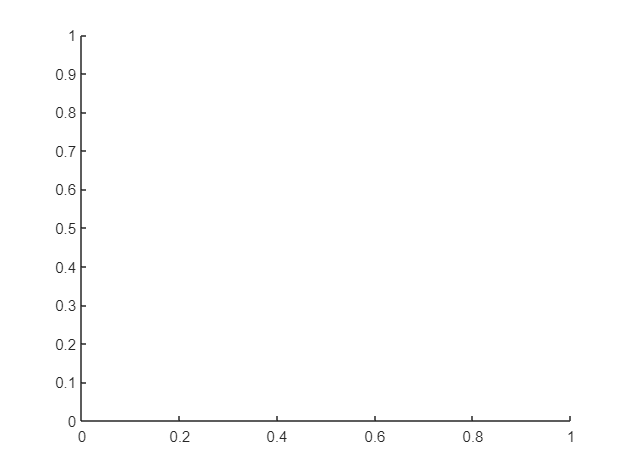

R = rotx(pi/2)
%tranimate(R)

## 2. Robot Manipulator

To rapresent robot in the toolbox we use the the `SerialLink `class which is a concatenation of `Link `class.

### creating a Link 

we can first define a DH `structure `and associate each field to a parameter of the DH convention

**example: 3 Link arm (RRRP)**

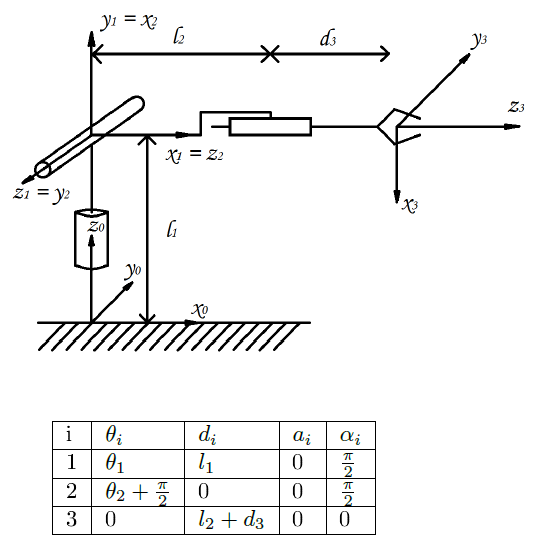

DH.theta = [0 0 0];

R =      1     0     0
     0     0    -1
     0     1     0


DH.
DH.a = [pi/2 pi/2 0];
